# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'figures/';

%What is the original data?
originaldata = 'CB_thawingdepth_hourly.txt';

%do you want the figure saved?
printfig  = true ;

%Where do you want to save files?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/datERRA/CB_years/figures/';

%Where is your data?
workdir = '~/Documents/GitHub/Permafrost_ERRA/rawdata';

%where is your ERRA data?
workdir_ERRA = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_years/Rresults/';


%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end



% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2*2};
FS = {'FontSize',10*3,15*3,18*3,21*3,30*3};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};
Colors = [203,201,226;
158,154,200;
106,81,163;
186,228,179;
116,196,118;
35,139,69;
253,190,133;
253,141,60;
217,71,1;
189,215,231;
107,174,214;
33,113,181
28,144,153]./255;

%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 1.1;
axt = 0.8;
axl = 1.2;
axr = 2.4;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;


%%%%%%% IMPORT DATA HERE
cd(workdir)
originaldata_ = {workdir, originaldata};
originaldata_loc =char(strcat(originaldata_(1),originaldata_(2)));
dataout = readfiles(originaldata)

dataout = 89100×13 table
    time_cont    years    months    airtemp    P     Q      ThawDepth      dZ        dw30      DOC     POC     SSC      TDS 
    _________    _____    ______    _______    _    ____    _________    _______    _______    ____    ____    ____    _____

     2007.4      2007       6        0.73      0    0.02          0       1.3463     4.0389    4.63    0.02    1.35    15.57
     2007.4      2007       6        0.29      0    0.02     1.3463      0.55765      1.673    4.63    0.02    1.35    15.57
     2007.4      2007       6   

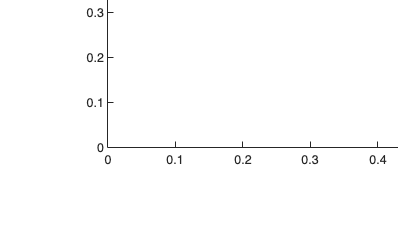

Precip = dataout.P;
DOC = dataout.DOC.*dataout.Q;
TDS = dataout.TDS.*dataout.Q;
POC = dataout.POC.*dataout.Q;
SSC = dataout.SSC.*dataout.Q;
short_t_cont = dataout.time_cont;
years = dataout.years;
months = dataout.months;
airtemp = dataout.airtemp;
Q = dataout.Q;
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


uni_years = unique(years)

uni_years =         2007
        2008
        2009
        2010
        2011
        2012
        2013
        2014
        2015
        2016


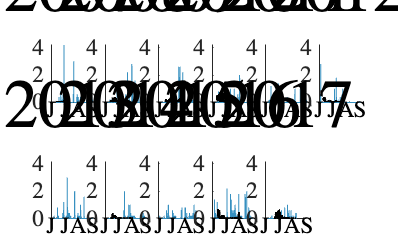


for l = 1: numel(uni_years)
        logindxYears = (years == uni_years(l));
        logindxMonths = (months > 5 & months<10);
        logindxMonthsJ = (months <= 5 );
        totaldata(l) = sum(logindxYears);
        totalP(l) = nansum(Precip(logindxYears));
        totalT(l) = nanmean(airtemp(logindxYears & logindxMonths));
        totalTJuly(l) = nanmean(airtemp(logindxYears & logindxMonthsJ));
        %%%%% here consider November and December by doing 
        logindxYears_prev = (years == uni_years(l)-1); 
        logindxMonthsW_prev = (months > 10);
        winter_temp = [airtemp(logindxYears & logindxMonthsJ); airtemp(logindxYears_prev & logindxMonthsW_prev)];
        av_winter(l) = nanmean(winter_temp);

        Q_year = Q(logindxYears);
        P_year = Precip(logindxYears);
        time = short_t_cont(logindxYears);
     

        % Define the number of hours in a week
            hours_per_week = 168;

        % Reshape the data into a matrix with one week per column
            num_weeks = floor(length(Q_year)/hours_per_week);
            time_matrix = reshape(time(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            Q_matrix = reshape(Q_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            P_matrix = reshape(P_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);

        % Calculate the mean of each column to get the weekly averages
            time_weekly_averages = nanmean(time_matrix, 1);
            Q_weekly_averages = nanmean(Q_matrix, 1);
            P_weekly_averages = nanmean(P_matrix, 1);
            maxQ(l) = max(Q_weekly_averages);

        subplot(2, 6, l)
%          figtQP_plot_UK_wiMatlab_years(time_weekly_averages,Q_weekly_averages,P_weekly_averages,.3)
        figtQP_plot_CB_wiMatlab_years(time,Q_year,P_year,4.2)
        title(uni_years(l),TX{:},FS{[1,4]},UN{[1,3]})
%         xlabel('t',TX{:},FS{[1,4]},UN{[1,3]});
%         ylabel('Q $\&$ P [mm/hr]',TX{:},FS{[1,4]},UN{[1,3]});
if l == 10
    xlabel('Months',TX{:},FS{[1,6]},UN{[1,3]},'Position',[0,-.3]);
end
if l == 1
    ylabel('Q $\&$ P [mm/hr]',TX{:},FS{[1,6]},UN{[1,3]},'Position',[-.5,-.5]);
end

end
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'precip_discharge_years_avs' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

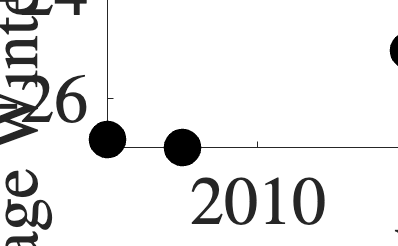

% years = uni_years;
% for l = 1: numel(years)
%         logindxYears = (Pyears == years(l));
%         logindxMonths = (Pmonths > 5 & Pmonths<10);
%         logindxMonthsJ = (Pmonths <= 5 );
%         totaldata(l) = sum(logindxYears);
%         totalP(l) = nansum(Precip(logindxYears));
%         totalT(l) = nanmean(airtemp(logindxYears & logindxMonths));
%         totalTJuly(l) = nanmean(airtemp(logindxYears & logindxMonthsJ)); 
%         %%%%% here consider November and December by doing 
%         logindxYears_prev = (Pyears == years(l)-1); 
%         logindxMonthsW_prev = (Pmonths > 10);
%         winter_temp = [airtemp(logindxYears & logindxMonthsJ); airtemp(logindxYears_prev & logindxMonthsW_prev)];
%         av_winter(l) = nanmean(winter_temp);
%         Q_year = Q(logindxYears);
%         P_year = Precip(logindxYears);
%         time = short_t_cont(logindxYears);
% 
% end


%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

hold on
% for jj = 1:numel(uni_years)
    plot(uni_years,av_winter,'.k','MarkerSize',45*2)%,'Color',Colors(jj,:))
% end
set(gca,TL{:},FS{[1,4]});

%set axis
xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Average Winter Temperatures [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'year_WinterTemp' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

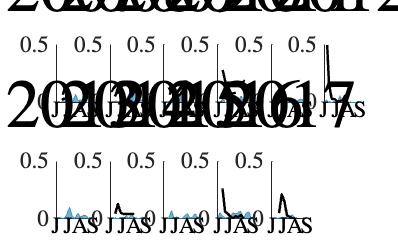


f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


for l = 1: numel(uni_years)
        logindxYears = (years == uni_years(l));
        logindxMonths = (months > 5 & months<10);
        logindxMonthsJ = (months <= 5 );
        totaldata(l) = sum(logindxYears);
        totalP(l) = nansum(Precip(logindxYears));
        totalT(l) = nanmean(airtemp(logindxYears & logindxMonths));
        totalTJuly(l) = nanmean(airtemp(logindxYears & logindxMonthsJ)); 
        %%%%% here consider November and December by doing 
        logindxYears_prev = (years == uni_years(l)-1); 
        logindxMonthsW_prev = (months > 10);
        winter_temp = [airtemp(logindxYears & logindxMonthsJ); airtemp(logindxYears_prev & logindxMonthsW_prev)];
        av_winter(l) = nanmean(winter_temp);
        Q_year = Q(logindxYears);
        P_year = Precip(logindxYears);
        time = short_t_cont(logindxYears);
     

        % Define the number of hours in a week
            hours_per_week = 168;

        % Reshape the data into a matrix with one week per column
            num_weeks = floor(length(Q_year)/hours_per_week);
            time_matrix = reshape(time(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            Q_matrix = reshape(Q_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            P_matrix = reshape(P_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);

        % Calculate the mean of each column to get the weekly averages
            time_weekly_averages = nanmean(time_matrix, 1);
            Q_weekly_averages = nanmean(Q_matrix, 1);
            P_weekly_averages = nanmean(P_matrix, 1);
            maxQ(l) = max(Q_weekly_averages);

        subplot(2, 6, l)
          figtQP_plot_CB_wiMatlab_years(time_weekly_averages,Q_weekly_averages,P_weekly_averages,.5)
%         figtQP_plot_UK_wiMatlab_years(time,Q_year,P_year,16)
        title(uni_years(l),TX{:},FS{[1,4]},UN{[1,3]})
if l == 10
    xlabel('Months',TX{:},FS{[1,6]},UN{[1,3]},'Position',[0,-.3]);
end
if l == 1
    ylabel('Q $\&$ P [mm/hr]',TX{:},FS{[1,6]},UN{[1,3]},'Position',[-.5,-.5]);
end

end

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'precip_discharge_years' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

% plot(av_winter, totalTJuly,'.','MarkerSize',35)

# What percent of precipitation is going to discharge each year? 

%Correct for data availability and check what percent of P goes to
%discharge, assuming no other contribution. 

for l = 1: numel(uni_years)
        % isnansPQ = ~isnan(Precip) &~isnan(Q);
        logindxYears = (years == uni_years(l));
        logindxTemp4 = airtemp>=4;
        logindxMonths = (months > 5 & months<9);
        logindxMissing = (~isnan(Precip) & ~isnan(Q));
        logindxMissing_DOC = (~isnan(Precip) & ~isnan(DOC));
        logindxMissing_POC = (~isnan(Precip) & ~isnan(POC));
        logindxMissing_TDS = (~isnan(Precip) & ~isnan(TDS));
        logindxMissing_SSC = (~isnan(Precip) & ~isnan(SSC));
        hourssum(l) = sum(logindxYears & logindxMonths);
        totaldata(l) = sum(logindxYears & logindxMonths & logindxMissing);
        totaldata_DOC(l) = sum(logindxYears & logindxMonths & logindxMissing_DOC);
        totaldata_POC(l) = sum(logindxYears & logindxMonths & logindxMissing_POC);
        totaldata_TDS(l) = sum(logindxYears & logindxMonths & logindxMissing_TDS);
        totaldata_SSC(l) = sum(logindxYears & logindxMonths & logindxMissing_SSC);
        totaldata_rain(l) = sum(logindxYears & logindxMonths & logindxMissing & logindxTemp4);
        totaldata_DOC_rain(l) = sum(logindxYears & logindxMonths & logindxMissing_DOC & logindxTemp4);
        totaldata_POC_rain(l) = sum(logindxYears & logindxMonths & logindxMissing_POC & logindxTemp4);
        totaldata_TDS_rain(l) = sum(logindxYears & logindxMonths & logindxMissing_TDS & logindxTemp4);
        totaldata_SSC_rain(l) = sum(logindxYears & logindxMonths & logindxMissing_SSC & logindxTemp4);



        totalP(l) = nansum(Precip(logindxYears & logindxMonths));
        totalQ(l) = nansum(Q(logindxYears &logindxMonths));
        totalDOC(l) = nansum(DOC(logindxYears &logindxMonths));
        totalPOC(l) = nansum(POC(logindxYears &logindxMonths));
        totalTDS(l) = nansum(TDS(logindxYears &logindxMonths));
        totalSSC(l) = nansum(SSC(logindxYears &logindxMonths));
        totalmeanP(l)= nanmean(Precip(logindxYears & logindxMonths)).*hourssum(l);
        totalmeanQ(l) = nanmean(Q(logindxYears & logindxMonths)).*hourssum(l); %for 3 months
        totalmeanDOC(l) = nanmean(DOC(logindxYears & logindxMonths)).*hourssum(l); %for 3 months
        totalmeanPOC(l) = nanmean(POC(logindxYears & logindxMonths)).*hourssum(l); %for 3 months
        totalmeanTDS(l) = nanmean(TDS(logindxYears & logindxMonths)).*hourssum(l); %for 3 months
        totalmeanSSC(l) = nanmean(SSC(logindxYears & logindxMonths)).*hourssum(l); %for 3 months
        PercentP(l) = totalQ(l)./totalP(l);
end



f2 = figure

f2 =   Figure (46) with properties:

      Number: 46
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1440 818 560 420]
       Units: 'pixels'

  Show all properties


set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

% for l = 1:numel(uni_years)
    hold on
plot(uni_years,totaldata./hourssum,'.k','MarkerSize',100)%,'Color',Colors(l,:))
plot(uni_years,totaldata_DOC./hourssum,'ok','MarkerSize',45,'LineWidth',3)%,'Color',Colors(l,:),'LineWidth',3)
plot(uni_years,totaldata_TDS./hourssum,'sk','MarkerSize',45,'LineWidth',3)
plot(uni_years,totaldata_SSC./hourssum,'*k','MarkerSize',35,'LineWidth',3) %,'Color',Colors(l,:)
% plot(uni_years,totaldata_POC./hourssum,'*k','MarkerSize',35,'LineWidth',3) %,'Color',Colors(l,:)

% % end
ylabel('Fraction of Hourly Summer Data Available',TX{:},FS{[1,5]},UN{[1,3]});
xlabel('Year',TX{:},FS{[1,5]},UN{[1,3]})
ylim([0 1])
set(gca, LW{[1,4]},TL{:},FS{[1,5]}, 'Box', 'on');
[lgd, hobj, ~, ~] = legend('Discharge','DOC','TDS','SS/POC','Location','northeast',TX{:},FS{[1,4]})

lgd =   Legend (Discharge, DOC, TDS, SS/POC) with properties:

         String: {'Discharge'  'DOC'  'TDS'  'SS/POC'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 54
       Position: [0.4216 0.3254 0.3275 0.5180]
          Units: 'normalized'

  Show all properties


hobj =   12×1 graphics array:

  Text    (Discharge)
  Text    (DOC)
  Text    (TDS)
  Text    (SS/POC)
  Line    (Discharge)
  Line    (Discharge)
  Line    (DOC)
  Line    (DOC)
  Line    (TDS)
  Line    (TDS)
  Line    (SS/POC)
  Line    (SS/POC)


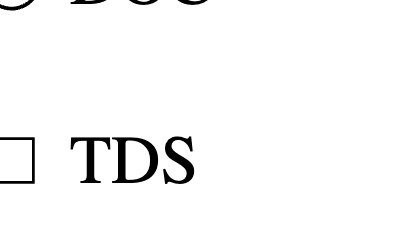

adjustLegendSize(lgd,hobj,1.05,1.00,10,1);
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'data_availability' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end



f2 = figure
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

for l = 1:numel(uni_years)
    hold on
plot(uni_years(l),totaldata_rain(l)./hourssum(l),'.','MarkerSize',35,'Color',Colors(l,:))
plot(uni_years(l),totaldata_DOC_rain(l)./hourssum(l),'o','MarkerSize',35,'Color',Colors(l,:),'LineWidth',3)
plot(uni_years(l),totaldata_POC_rain(l)./hourssum(l),'*','MarkerSize',35,'Color',Colors(l,:),'LineWidth',3)
plot(uni_years(l),totaldata_SSC_rain(l)./hourssum(l),'x','MarkerSize',35,'Color',Colors(l,:),'LineWidth',3)
end
ylabel('Fraction of Hourly Summer Data available and $\ge 4^{\circ}$C',TX{:},FS{[1,6]},UN{[1,3]});
xlabel('Years',TX{:},FS{[1,6]},UN{[1,3]})
ylim([0 1])
set(gca,TL{:},FS{[1,4]});
legend('Discharge','DOC','POC','SSC','Location','northwest',TX{:},FS{[1,4]})
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'data_availability_rain' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end


f1=figure
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

for l = 1:numel(uni_years)
    hold on
    plot(uni_years(l),totalmeanQ(l),'.','MarkerSize',35,'Color',Colors(l,:))
end
ylabel('Annual Summer Discharge (Q) [mm]',TX{:},FS{[1,6]},UN{[1,3]});
xlabel('Years',TX{:},FS{[1,6]},UN{[1,3]})
set(gca,TL{:},FS{[1,4]});

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'yrs_summerQ' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end


f1=figure
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

% for l = 1:numel(uni_years)
    hold on
    plot(uni_years,totalmeanP,'.k','MarkerSize',45*2)%,'Color',Colors(l,:))
% end

%set axis
xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Average Summer Precipitation (P) [mm]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  
set(gca,TL{:},FS{[1,4]});

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'yrs_summerP' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end



f1 = figure
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

for l = 1:numel(uni_years)
    hold on
    plot(totalmeanP(l),totalmeanQ(l),'.','MarkerSize',35,'Color',Colors(l,:))
end
xlabel('Total Precip')
ylabel('Total Discharge')
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'meanP_meanQ' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end


% %set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


years_check = [2009, 2012, 2014, 2016, 2017];
maxRRD = zeros(size(uni_years));
maxRRDlgt = zeros(size(uni_years));
% RRD = zeros(numel(years),2000);
% se  = zeros(numel(years),2000);
% lagt = zeros(numel(years),2000);

%state the range of lag time to consider
hourrange = [0 20];
hourlimit = 0;


for jj = 1:numel(years_check) 
str = {'Rresults/1hr_simple_',mat2str(years_check(jj)),'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),maxRRDse(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_years_thaw(filename,workdir_ERRA,Colors(jj,:),hourlimit,hourrange, "P");

end
if hourlimit
    xline(hourrange(1),'LineWidth',3,'Color',[0.65 0.85 0.90])
    xline(hourrange(2),'LineWidth',3,'Color',[0.65 0.85 0.90])
end

set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('Hour lag [hr]',TX{:},FS{[1,4]},UN{[1,3]});
ylabel('Runoff Response Distribution [1/hr]',TX{:},FS{[1,4]},UN{[1,3]});
legend(num2str(years_check.'), 'Location', 'northeast','NumColumns', 2);
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

hold on
for jj = 1:numel(years_check)
    plot(years_check(jj),maxRRDlgt(jj),'.','MarkerSize',35*2,'Color',Colors(jj,:))
end
set(gca,'XLim',[min(years_check),max(years_check)],'Ylim',[0, max(maxRRDlgt)],TL{:},FS{[1,4]});

%set axis
xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('lag hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'laghour_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end
%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
for jj = 1:numel(years_check)
    plot(years_check(jj),maxRRD(jj),'.','MarkerSize',45*2,'Color',Colors(jj,:))
end
set(gca,'XLim',[min(years_check),max(years_check)],'Ylim',[0, max(maxRRD)],TL{:},FS{[1,5]});

%set axis
xlabel('Year',TX{:},FS{[1,5]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Peak Runoff Response Distribution [1/hr]',TX{:},FS{[1,5]},UN{[1,3]},'Position',[-2.*axl/3,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end


% %set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);


years_check = [2009, 2012, 2014, 2016, 2017];
maxRRD = zeros(size(uni_years));
maxRRDlgt = zeros(size(uni_years));
% RRD = zeros(numel(years),2000);
% se  = zeros(numel(years),2000);
% lagt = zeros(numel(years),2000);

%state the range of lag time to consider
hourrange = [0 5];
hourlimit = 1;


for jj = 1:numel(years_check) 
str = {'Rresults/1hr_simple_',mat2str(years_check(jj)),'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),maxRRDse(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_years_thaw(filename,workdir_ERRA,Colors(jj,:),hourlimit,hourrange, "T");

end
if hourlimit
    xline(hourrange(1),'LineWidth',3,'Color',[0.65 0.85 0.90])
    xline(hourrange(2),'LineWidth',3,'Color',[0.65 0.85 0.90])
end

set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('Hour lag [hr]',TX{:},FS{[1,4]},UN{[1,3]});
ylabel('Thaw Runoff Response Distribution [1/hr]',TX{:},FS{[1,4]},UN{[1,3]});
legend(num2str(years_check.'), 'Location', 'northeast','NumColumns', 2);
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD_thaw' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

hold on
for jj = 1:numel(years_check)
    plot(years_check(jj),maxRRDlgt(jj),'.','MarkerSize',35*2,'Color',Colors(jj,:))
end
set(gca,'XLim',[min(years_check),max(years_check)],'Ylim',[0, max(maxRRDlgt)],TL{:},FS{[1,4]});

%set axis
xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('lag hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'laghour_year_thaw' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
for jj = 1:numel(years_check)
    plot(years_check(jj),maxRRD(jj),'.','MarkerSize',45*2,'Color',Colors(jj,:))
end
set(gca,'XLim',[min(years_check),max(years_check)],'Ylim',[0, max(maxRRD)],TL{:},FS{[1,5]});

%set axis
xlabel('Year',TX{:},FS{[1,5]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Peak Runoff Response Distribution [1/hr]',TX{:},FS{[1,5]},UN{[1,3]},'Position',[-2.*axl/3,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD_year_thaw' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end



## Save files to txt

%First make a table
WinterTemp = av_winter'; 
Precipitation = totalP'; 
% mRRD = maxRRD';
zWinterTemp = zscore(av_winter)'; 
zPrecipitation = zscore(totalP)'; 
% zmRRD = zscore(maxRRD)';
years = years';
% Mtxt = table(years,WinterTemp,Precipitation,mRRD,...
%     zWinterTemp,zPrecipitation,zmRRD);
% writetable(Mtxt,'ModelParams','WriteRowNames',true,'Delimiter',',');
%     TDat = [WinterTemp,Precipitation,mRRD];
